# Sample 13-2

## 辞書学習

再構成独立成分分析

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Dictionary learning

Reconstruction ICA

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

kodim01.png already exists in ./data/
kodim02.png already exists in ./data/
kodim03.png already exists in ./data/
kodim04.png already exists in ./data/
kodim05.png already exists in ./data/
kodim06.png already exists in ./data/
kodim07.png already exists in ./data/
kodim08.png already exists in ./data/
kodim09.png already exists in ./data/
kodim10.png already exists in ./data/
kodim11.png already exists in ./data/
kodim12.png already exists in ./data/
kodim13.png already exists in ./data/
kodim14.png already exists in ./data/
kodim15.png already exists in ./data/
kodim16.png already exists in ./data/
kodim17.png already exists in ./data/
kodim18.png already exists in ./data/
kodim19.png already exists in ./data/
kodim20.png already exists in ./data/
kodim21.png already exists in ./data/
kodim22.png already exists in ./data/
kodim23.png already exists in ./data/
kodim24.png already exists in ./data/
See <a href="http://www.r0k.us/graphics/kodak/">Kodak Lossless True Color Image Suite</a

### パラメータ設定

(Parameter settings)

- ブロックサイズ (Block size)

- 冗長率 (Redundancy ratio)

- 正則化パラメータ (Regularization parameter)

- 繰返し回数 (Number of iterations)

- 正則化パラメータ (Regularization parameter)

% Block size
szBlk = [ 8 8 ];

% Redundancy ratio 
redundancyRatio = 7/3; 

% Sparsity ratio 
sparsityRatio = 3/64;

% Number of iterations
nItersRica = 1e5; 

% Regularization parameter
alpha = 2e-3;

## 画像の読込

(Read image)

- 
$$\mathbf{u}\in\mathbb{R}^{N}$$


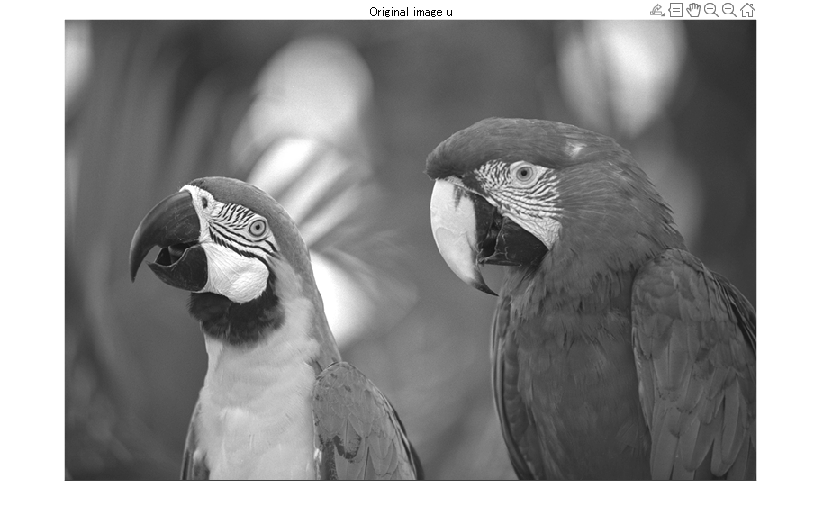

file_uorg = './data/kodim23.png';
u = im2double(imread(file_uorg));
if size(u,3) == 3
    u = rgb2gray(u);
end
szOrg = size(u);
figure
imshow(u);
title('Original image u')

#### 画像 $\mathbf{y}$からのデータ行列 $\mathbf{Y}$ の生成 

(Generate data matrices from images )

標本平均ブロックを引く代わりに，予め零平均化したデータで学習(Instead of subtracting the sample average block, training with pre-zero averaged data)

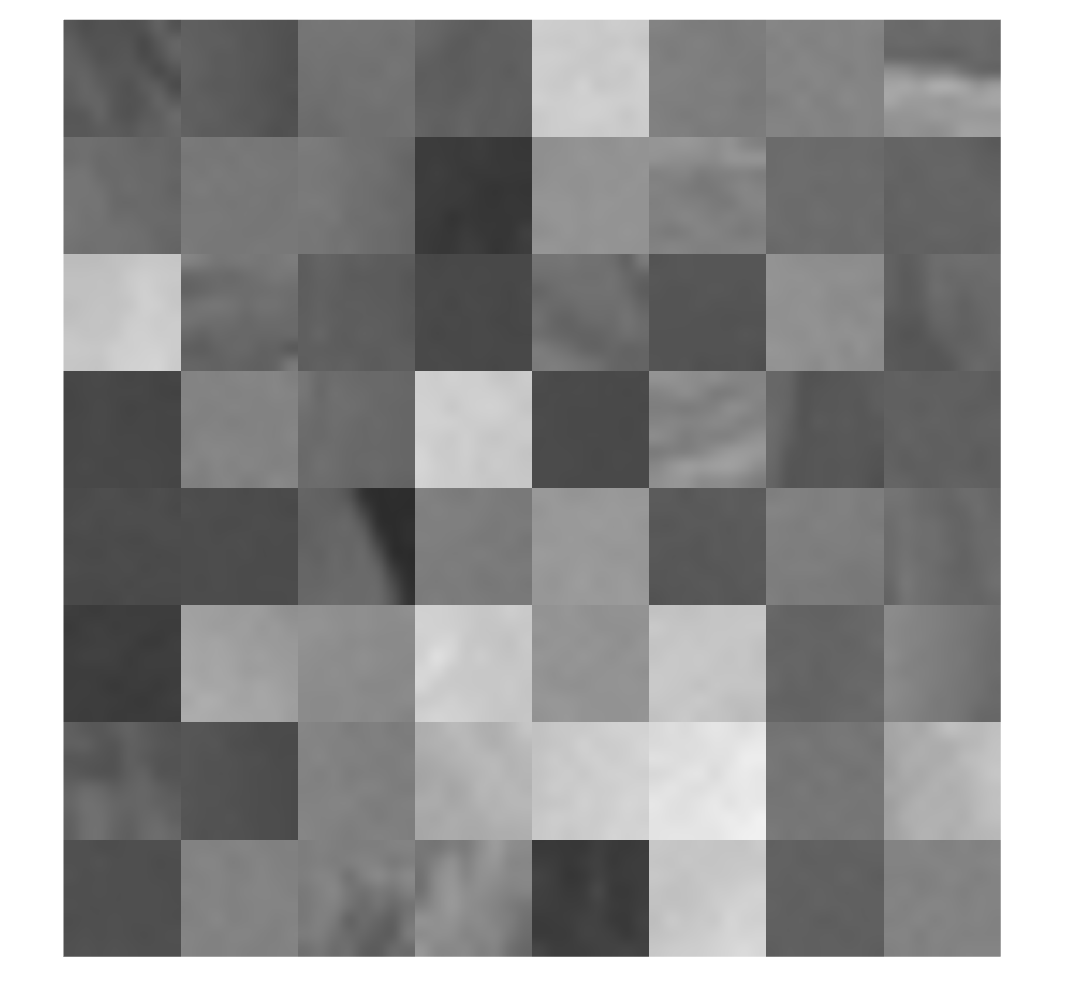

meansubtract = @(x) x-mean(x,"all");
y = meansubtract(u);

% # of patches
nPatches = prod(szOrg./szBlk); 

npos = randsample(prod(szOrg-szBlk),nPatches);
ybs = zeros(szBlk(1),szBlk(2),nPatches,'like',y);
szSrchy = szOrg(1)-szBlk(1);
for iPatch = 1:nPatches
    ny_ = mod(npos(iPatch)-1,szSrchy)+1;
    nx_ = floor((npos(iPatch)-1)/szSrchy)+1;
    ybs(:,:,iPatch) = y(ny_:ny_+szBlk(1)-1,nx_:nx_+szBlk(2)-1);
end
figure
montage(ybs+0.5,'Size',[8 8]);

drawnow

Y = reshape(ybs,prod(szBlk),[]);

## 再構成独立成分分析

(Reconstruction ICA)

#### 問題設定 (Problem setting):

        
$$\widehat{\mathbf{\Phi}}=\arg \max _{\mathbf{\Phi}} \frac{1}{2S}\sum_{n=1}^S\|\mathbf{y}_n-\mathbf{\Phi}\mathbf{\Phi}^T\mathbf{y}_n\|_2^2+\frac{\alpha}{S}\sum_{n=1}^{S}\rho(\mathbf{\Phi}^T\mathbf{y}_n)
$$


            
$$=\arg \max _{\mathbf{\Phi}} \frac{(2\alpha)^{-1}}{S}\sum_{n=1}^S\|\mathbf{y}_n-\mathbf{\Phi}\mathbf{\Phi}^T\mathbf{y}_n\|_2^2+\frac{1}{S}\sum_{n=1}^{S}\rho(\mathbf{\Phi}^T\mathbf{y}_n)$$


ただし，  $\{\mathbf{y}_n\}_n\subset\mathbb{R}^{M}$,  $\mathbf{\Phi}=(\mathbf{\phi}_1,\mathbf{\phi}_2,\cdots,\mathbf{\phi}_P)\in\mathbb{R}^{M\times P}$, $M\geq P$ である．(where，$\{\mathbf{y}_n\}_n\subset\mathbb{R}^{M}$ and  $\mathbf{\Phi}=(\mathbf{\phi}_1,\mathbf{\phi}_2,\cdots,\mathbf{\phi}_P)\in\mathbb{R}^{M\times P}$, $M\geq P$.)

#### 参考文献 (Reference):

Le, Quoc V., Alexandre Karpenko, Jiquan Ngiam, and Andrew Y. Ng. “ICA with Reconstruction Cost for Efficient Overcomplete Feature Learning.” Advances in Neural Information Processing Systems. Vol. 24, 2011, pp. 1017–1025. https://papers.nips.cc/paper/4467-ica-with-reconstruction-cost-for-efficient-overcomplete-feature-learning.pdf. 

コントラスト関数の例 (Example of contrast function)

        
$$\rho(\mathbf{\Phi}^T\mathbf{y})\colon = \frac{1}{2}\sum_{p=1}^{P}\log\circ\cosh(2\mathbf{\phi}_p^T\mathbf{y})$$


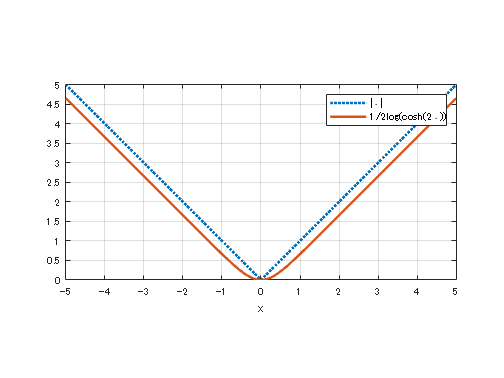

figure
fplot(@(x) abs(x),[-5 5],':','LineWidth',2,'DisplayName','|\cdot|')
hold on
fplot(@(x) log(cosh(2*x))/2,[-5 5],'-','LineWidth',2,'DisplayName','1/2log(cosh(2\cdot))')
xlabel('x')
legend
grid on
axis equal
hold off

要素画像の数 (Number of atomic images)

nDims = prod(szBlk);
nAtoms = ceil(redundancyRatio*nDims);

辞書 $\mathbf{\Phi}$の初期化 (Initializatio of dictionary $\mathbf{\Phi}$)

- 二変量離散コサイン変換(Bivariate DCT)

- ランダム (random)

Phi_rica = randn(nDims,nAtoms);
Phi_rica = Phi_rica/norm(Phi_rica,'fro');
for iAtom = 1:nDims
    delta = zeros(szBlk);
    delta(iAtom) = 1;
    Phi_rica(:,iAtom) = reshape(idct2(delta),nDims,1);
end

要素ベクトルを要素画像に変換 (Reshape the atoms into atomic images)

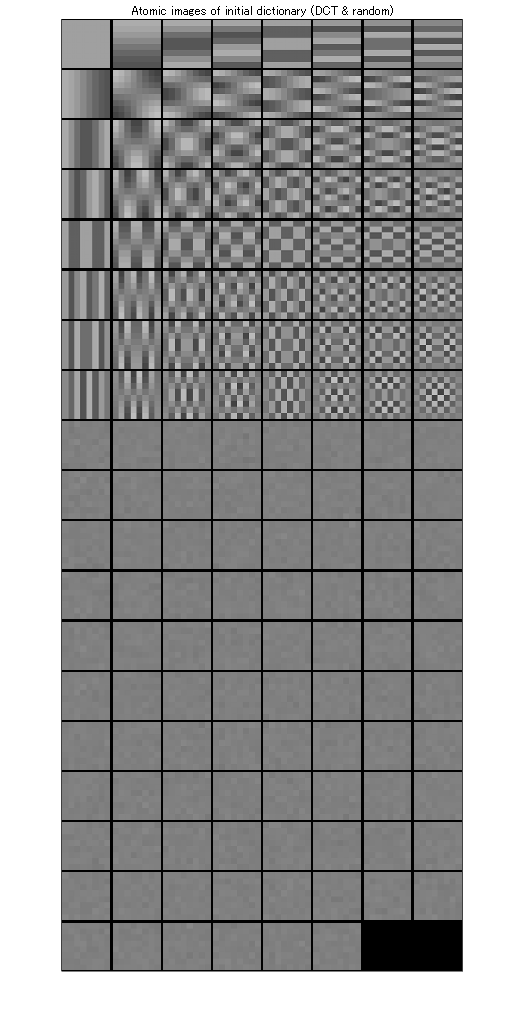

atomicImagesRica = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImagesRica(:,:,iAtom) = reshape(Phi_rica(:,iAtom),szBlk(1),szBlk(2));
end
figure
montage(imresize(atomicImagesRica,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of initial dictionary (DCT & random)')

#### 再構成 ICA オブジェクトの作成 (Creation of reconstructio ICA object)

model = rica(Y.',nAtoms,...
    'IterationLimit',nItersRica,...
    'ContrastFcn','logcosh',...
    'InitialTransformWeight',Phi_rica,...
    'Lambda',1/(2*alpha));

コスト評価のグラフ (Graph of cost variation)

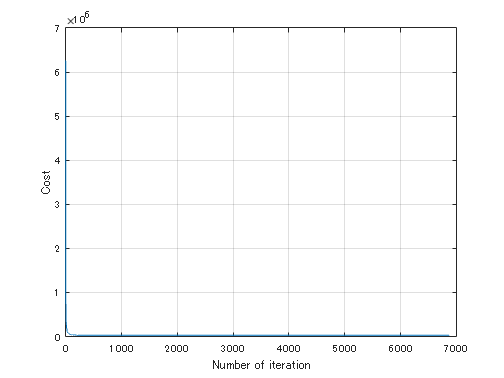

info = model.FitInfo;
figure
plot(info.Iteration,info.Objective)
xlabel('Number of iteration')
ylabel('Cost')
grid on

要素ベクトルを要素画像に変換 (Reshape the atoms into atomic images)

Phi_rica = model.TransformWeights;
atomicImagesRica = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImagesRica(:,:,iAtom) = reshape(Phi_rica(:,iAtom),szBlk(1),szBlk(2));
end


#### 要素画像の表示

(Show atomic images)

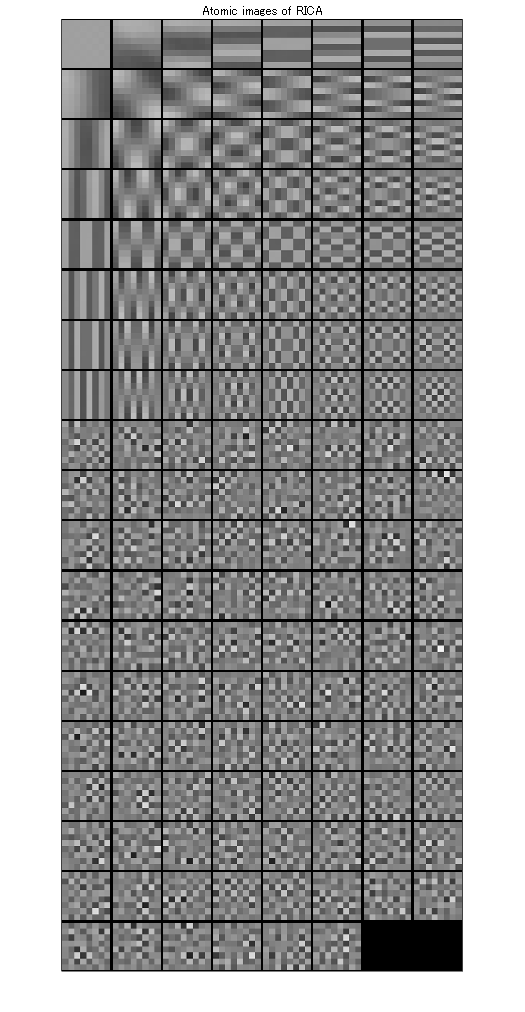

figure
montage(imresize(atomicImagesRica,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of RICA')

© Copyright, 2018-2023, Shogo MURAMATSU, All rights reserved.